**Load image**

img = imread('Fig0441(a)(characters_test_pattern).tif'); 
[M, N] = size(img);

**Define cutoff frequencies**

D0_values = [30, 60, 160];

**Create frequency coordinates**

[U, V] = meshgrid(-N/2:N/2-1, -M/2:M/2-1);
D = sqrt(U.^2 + V.^2);

**Apply Gaussian Low Pass Filter and display the original image and results**

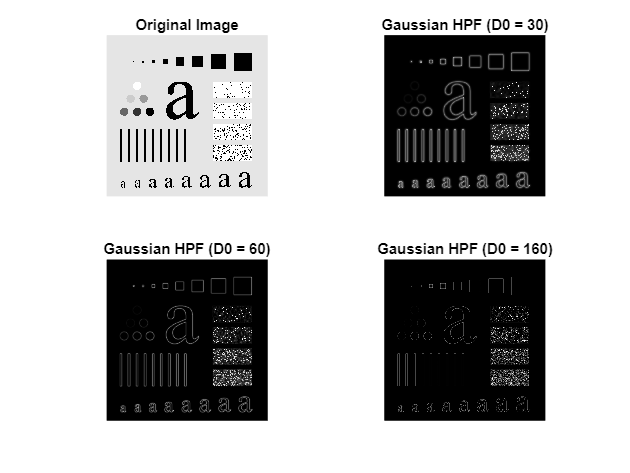

figure;

subplot(2, 2, 1);
imshow(img, []); 
title('Original Image');

for i = 1:length(D0_values)
    D0 = D0_values(i);
    
    H = 1 - exp(-(D.^2) / (2 * (D0^2)));
    
    img_fft = fftshift(fft2(img));
    img_fft_filtered = H .* img_fft;
    img_filtered = abs(ifft2(ifftshift(img_fft_filtered)));
    
    subplot(2, 2, i+1);
    imshow(img_filtered, []); 
    title(['Gaussian HPF (D0 = ', num2str(D0), ')']);
end